# Ex. 2.4 (1)

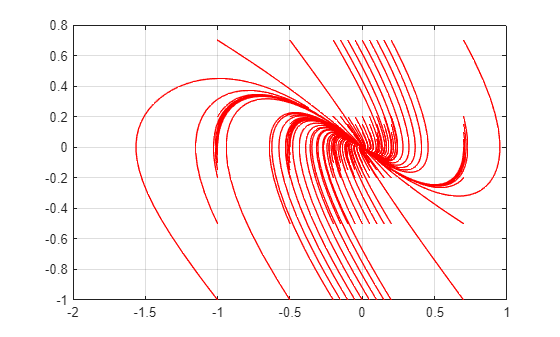

x10 = [-1: 0.5 : -0.2, -0.2 : 0.05: 0.21, 0.2: 0.5: 1  ];
x20 = [-1: 0.5 : -0.2, -0.2 : 0.05: 0.21, 0.2: 0.5: 1  ];



for x10_ = x10
    for x20_ = x20
F = ode;
F.InitialValue = [x10_; x20_];
F.ODEFcn = @(t,y) [y(2); y(1) - 2*atan(y(1) + y(2))];
F.Solver = "ode45";
%F.SolverOptions.OutputFcn = @odephas2;

S = solve(F,0,5);
plot(S.Solution(1, :), S.Solution(2, :), Color="r");
hold("on")
    end
end
grid("on")

## Ex. 2.4 (2)

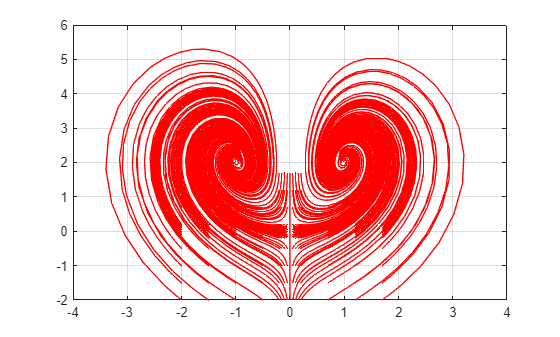

close all;
x10 = [-2: 0.5 : -0.2, -0.2 : 0.05: 0.21, 0.2: 0.5: 2  ];
x20 = [-2: 0.5 : -0.2, -0.2 : 0.05: 0.21, 0.2: 0.5: 2  ];
for x10_ = x10
    for x20_ = x20
F = ode;
F.InitialValue = [x10_; x20_];
F.ODEFcn = @(t,y) [2*y(1) - y(1)*y(2); 2*y(1)^2 - y(2)];
F.Solver = "ode45";
%F.SolverOptions.OutputFcn = @odephas2;

S = solve(F,0,5);
plot(S.Solution(1, :), S.Solution(2, :), Color="r");
hold("on")
    end
end
grid("on")

## Ex. 2.4 (3)

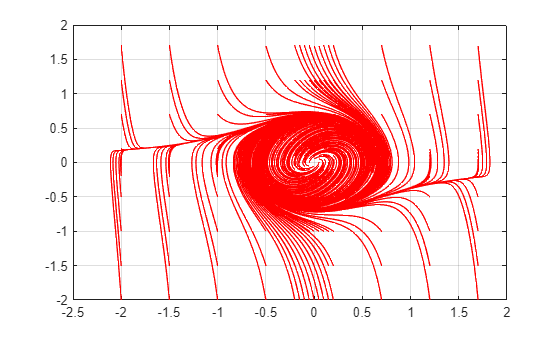

close all;
x10 = [-2: 0.5 : -0.2, -0.2 : 0.05: 0.21, 0.2: 0.5: 2  ];
x20 = [-2: 0.5 : -0.2, -0.2 : 0.05: 0.21, 0.2: 0.5: 2  ];
for x10_ = x10
    for x20_ = x20

F = ode;

F.InitialValue = [x10_; x20_];
F.ODEFcn = @(t,y) [y(2); -y(1) + y(2)*(1 - 3*y(1)^2 - 2*y(2)^2)];
F.Solver = "ode45";
%F.SolverOptions.OutputFcn = @odephas2;

S = solve(F,0,5);
plot(S.Solution(1, :), S.Solution(2, :), Color="r");
hold("on")
    end
end
grid("on")